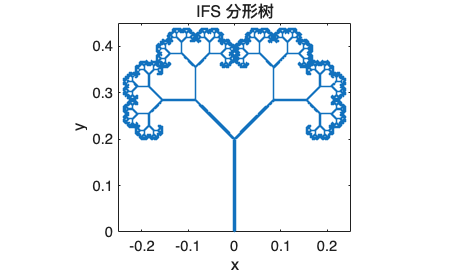

clc; clear; close all;

N = 100000;
x = zeros(N,1);
y = zeros(N,1);
x(1) = 0;
y(1) = 0;

for n = 1:N-1
    r = rand;   % [0,1) 的随机数
    if r < 0.05
        x(n+1) = 0.01 * x(n);
        y(n+1) = 0.45 * y(n);
    elseif r < 0.20
        x(n+1) = -0.01 * x(n);
        y(n+1) = -0.45 * y(n) + 0.2;
    elseif r < 0.60
        x(n+1) = 0.42 * x(n) - 0.42 * y(n);
        y(n+1) = 0.42 * x(n) + 0.42 * y(n) + 0.2;
    else
        x(n+1) = 0.42 * x(n) + 0.42 * y(n);
        y(n+1) = -0.42 * x(n) + 0.42 * y(n) + 0.2;
    end
end

burnin = 100;
x = x(burnin:end);
y = y(burnin:end);

% 作图
figure;
plot(x, y, '.', 'MarkerSize', 1);
axis equal;
axis([-0.25 0.25 0 0.45]);
xlabel('x');
ylabel('y');
title('IFS 分形树');